## Öksürük Sesleri ile Covid-19 Testi

Bu çalışma **Covid19 hastalığını öksürük sesleriniz ile yapay öğrenme metodları kullanarak evden çıkmadan teşhis etmek ve hastalığın sürecini izlemek** için yapılmıştır.

### Öksürük Nedir?

**Öksürük**, akciğerlerdeki havanın spazmdık bir şekilde çıkması olarak tanımlanır.

Solunum sesleri ile birlikte öksürük,Akciğer hastalıklarının en belirgin semptomudur. Öksürük verilerini inceleyerek akciğerlerin sağlığı veya hastalığı konusunda birçok klinik veriye ulaşabiliriz.

Öksürük çoğu zaman hastalık anında ortaya çıkar. Hastalık anında ortaya çıkan ve devam eden öksürüğe kronik öksürük denir. Bu tip öksürükler kişinin **hastalığına, yaşına ve cinsiyetine**göre farklılık gösterir.

Öksürük çoğu zaman hastalık anında ortaya çıkar. Hastalık anında ortaya çıkan ve devam eden öksürüğe kronik öksürük denir. Bu tip öksürükler kişinin **hastalığına, yaşına ve cinsiyetine**göre farklılık gösterir.

Öksürüğü ölçmek ve ondan anlamlı tanı bilgileri elde etmek için **kullanılan metrikler **şunlardır:

- Gücü ( Ne kadar güçlü olduğu )

- Yoğunluğu (1 saatteki ortalama öksürük sayısı )

- Tipi (Kuru, nemli, hırıltılı, boğuk, barking)

### Covid-19 Testleri

Koronavirüs hastalığı (COVID 19) pandemisinin başlaması ile birlikte, bu hastalığın yayılmasının önüne geçmek için bir çok tanı testi geliştirilmiştir. Bu testler, hastaların toplumdan izole edilmesi ve hastalığın seyrinin gözlenmesi konusunda temel rol oynamaktadırlar ve hastalığı teşhis edebilmek için kan örneği veya mukus örneği kullanırlar. Günümüzde en yaygın kullanılan testler RT-qPCR, antijen and antibody testleridir. Ancak bu testlerin birçok dezavantajı bulunmaktadır. Çoğu, uygulanması için bir uzmana ihtiyaç duyar. Maddi ve zaman olarak da çok elverişli değildirler. 

Dünya sağlık örgütünün raporuna göre **Covid-19 hastalarının % 67,7'sinde kuru öksürük önemli bir şikayettir.** [[DSÖ](https://www.who.int/docs/default-source/coronaviruse/who-china-joint-mission-on-covid-19-final-report.pdf)]  Kuru öksürük, içinde mukus olmayan öksürük demektir. Alerji, grip veya nezlenin sebep olduğu ıslak öksürüğe göre ses yapısı oldukça farklıdır. Bizler Covid-19 virüsünün sebep olduğu kuru öksürüğün, hastalık hakkında önemli klinik bilgiler verdiğini düşünüyoruz ve bu hastalığı öksürük seslerini kullanarak hızlı, ucuz ve ücretsiz bir şekilde test edebilmeyi umuyoruz.

### Öksürük Sesleri ile yapılan çalışmalar

Bir çok araştırma, koronavirüs hastalığını X-RAY resimlerine bakarak yüksek doğruluk oranı ile ayırmayı başarmıştır. [[1](https://towardsdatascience.com/using-deep-learning-to-detect-ncov-19-from-x-ray-images-1a89701d1acd),[2](https://arxiv.org/pdf/2003.13145.pdf)] Bu sonuç; virüsün akciğerlere verdiği zararın, diğer solunum yolu hastalıklarının verdiği zarara göre çok daha farklı olduğunu göstermektedir. Bu farklılığın öksürük ve solunum seslerine yansımasını araştırmak ve bu konuda test geliştirmek ise umut vaad edici bir alandır. Bu konuda, çalışmalar yapılmakta ve bütün dünyadan öksürük sesleri toplanmaya başlanmıştır. [[EPFL Çalışması](https://coughvid.epfl.ch/)] [[University of Cambridge Çalışması](https://www.covid-19-sounds.org/en/)]

Ayrıca, şu çalışmalar [[çalışma 1](https://journals.plos.org/plosone/article?id=10.1371/journal.pone.0162128)] [[çalışma 2](https://ieeexplore.ieee.org/document/7311223)] zatüreeyi daha önce öksürük sesiyle ayırt etmişler ve yüksek doğruluk oranına ulaşmışlardır.

### Çalışmanın Amacı

Bizler Covid-19 virüsünün sebep olduğu öksürüğün, hastalık hakkında önemli klinik bilgiler verdiğini düşünüyor ve bu hastalığı öksürük seslerini kullanarak hızlı, ucuz ve ücretsiz bir şekilde test edebilmeyi umuyoruz.

### DATASET

Datasetimde internette bulduğum ses dosyalarından oluşturdum. Bunlar:

[Covid 19 öksürük sesi 1](https://www.youtube.com/watch?v=CMmsscVN-js) (3-6 saniyeleri) ve (67 - 70 saniyeleri)

[Covid 19 öksürük sesi 2](https://www.youtube.com/watch?v=GwFmk6PgmqI) (8 - 12 saniye arasında)

[Covid 19 öksürük sesi 3](https://www.youtube.com/watch?v=EZxcEljV6WA) (Bir çok yerde)

[Normal öksürük sesi 1](https://www.youtube.com/watch?v=i_hI3gVoRr0&t=63s)    (Bir çok kişiden, Video mayıs 2018 tarihli olduğu için hiçbir öksürük koronavirüsün sebepli değil.)

Bu videoların sadece seslerini alarak, öksürük olan ses parçalarını kestim. Elimde 10 tane farklı uzunluklarda korona virüs hastalığı öksürüğü oldu. Normal öksürüklerden de 10 tane öksürük sesini kestim. 

Böylece toplam **2****0 tane öksürük sesi **bulunan bir dataset yarattım.

### DATASET HAZIRLANMASI

Datasetimdeki her bir öksürük sesi farklı uzunluklara sahiptir ve bu ses parçaları 44100 sample rate'ine 16 bit sample çözünürlüğüne sahiptir. Herbir ses parçasını %25 overlap ile 1024 sample'lık pencerelere böldüm. Herbir pencere yaklaşık 23 ms'dır. Bu da feature extaction için yeterli bir uzunluktur. Daha sonra her bir window'un ana ses içerisindeki indislerini, hangi öksürük videosuna ait olduğunu ve label'ını bir tablo içinde topladım. 

Raw Seslerinin bulunduğu dataSet:

clc;
clear;

addpath('functions');
addpath('dataSets');

load('coughSet.mat')
sound(dataSet(6).SoundData,44100);

Windowlanmış seslerin bulunduğu dataSet:

load('windowedCoughSet.mat');

disp("length of windows: "+length(dataSet));

length of windows: 2201


Görüldüğü gibi dataSetimde 2201 tane window bulunmaktadır. Bu windowindowlardan 955 tanesi Covidli öksürük (1) olarak işaretlenmiş, geri kalan 1246 tanesi normal öksürüklü (0) olarak işaretlenmiştir.

### FEATURE SET HAZIRLANMASI

Bu çalışma için yedi tane feature kullandım. Bu feature'lar daha önce hatalıklı seslerin normal solunum seslerinden ayrıştırlması için kullanılan ve yüksek ayırıcı özellikleri olduğu düşünülen feature'lar arasından seçilmiştir. Bu makalede, [[Evaluation of features for classification of wheezes and normal respiratory sounds](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC6414007/)], şu ana kadar akciğer seslerinden hırıltı ayrımı yapabilmek için akademik makalelerde kullanılan bütün feature'lar karşılaştırılmıştır. Bu çalışmadaki feature'lar hem bu makalenin başarılı bulduğu hem de tecrübelerimizle başarılı olabiliceğini düşündüğüm feature'lardır.

- Kurtosis

- Renyi Entropies with order 1,2, and 3

- Percentile Frequency Ratios (f25/f75, f25/f90, f50/f90, f50/f75)

- Mean Crossing Irregularity

- AR Parameters (Yule-Walker -> LPC Paramters)

- Mell Frequency Cepstral Coefficients

- Tonality Index

% Kurtosis
dataSet=findKurtosis(dataSet);
disp("Kurtosis is finished.");

Kurtosis is finished.


% F25/F75
dataSet=Ratio_of_25_to_75(dataSet);
disp("F25/F75 is finished.");

F25/F75 is finished.


% F25/F90
dataSet=Ratio_of_25_to_90(dataSet);
disp("F25/F90 is finished.");

F25/F90 is finished.


% F50/F75
dataSet=Ratio_of_50_to_75(dataSet);
disp("F50/F75 is finished.");

F50/F75 is finished.


% F50/F90
dataSet=Ratio_of_50_to_90(dataSet);
disp("F50/F90 is finished.");

F50/F90 is finished.


% Mean Crossing Irregularity
dataSet=calcZeroCrIr(dataSet);
disp("Mean Crossing Irr is finished.");

Mean Crossing Irr is finished.


% AutoRegressive Parameters
dataSet = ArCalc(dataSet);
disp("AR parameters is finished.");

AR parameters is finished.


% Tonality Index
dataSet = tonalityCalc(dataSet);
disp("TonalityIndex is finished.");

TonalityIndex is finished.


% MFCC
dataSet = calcMFCC(dataSet);
disp("MFCC is finished.");

MFCC is finished.


% Renyi Entropy
dataSet = calcRenyiEntropy(dataSet);
disp("Renyi is finished.");

Renyi is finished.


disp("All is well");

All is well


Data set'i training için hazır hale getirdim.

% Training için hazırlama
T = struct2table(dataSet);
T = removevars(T, 'winSound');
T = removevars(T, 'winInds');
T = removevars(T, 'tonalMag');
T = removevars(T, 'phi_sav');
T = removevars(T, {'cm','energy','spectUnPred'});
T(1:2,:) = [];
T.TI = cell2mat(T.TI);
[row, col] = find(isnan(T{:,:}));
T(row,:) = [];
isCovid = [T.label];
T(isCovid == 1,12) = {'covid'};

T(isCovid == 0,12) = {'normal'};
T.Properties.VariableNames{12} = 'isCovid';
T = movevars(T, 'isCovid', 'Before', 'kurtosis');
T = splitvars(T, 'renyi');
T = splitvars(T, 'ArParams');
T.Properties.VariableNames{15} = 'Ar_Error';
T = splitvars(T, 'MFCCParams');

### CLASSIFIER SEÇİMİ

Bu training set ile denediğim classiferlar şunlardır:

- KNN (k = 9)

- Linear SVM (C=1)

- Poynomial SVM order 3 (C = 1, Kernel Scale = 4.7)

- Gaussian SVM (C = 1, Kernel Scale = 2.5)

- Maximum Likelihood with Multivariate Gaussian

- Binary Decision Tree (max numb of splits: 100 ve Gini's diversity index)

Bütün sınıflandırıcılar ile data sayımız düşük olduğu için 5-fold cross validation yapıldı. Performansları karşılaştırıldı. Binary Decision Tree en iyi sonucu veren sınıflandırıcı oldu. Perfromansına aşağıdan bakabilirsiniz.

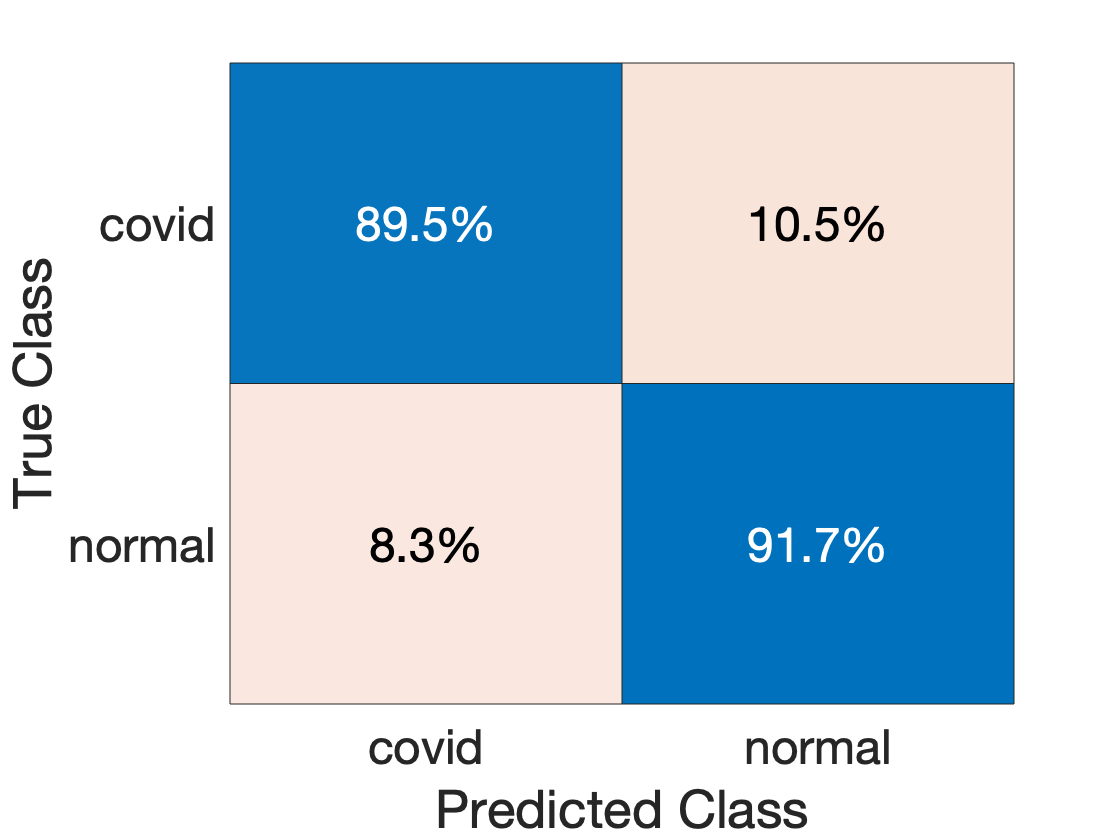

randoms = randperm(size(T,1));

X_label = T(:,2);
X = T(:,3:end);

X_train = X(randoms(1:size(T,1)),1:end);
X_train_label = table2cell( X_label(randoms(1:size(T,1)),1));

% Model
classificationTree = fitctree(...
    X_train, ...
    X_train_label, ...
    'SplitCriterion', 'gdi', ...
    'MaxNumSplits', 100, ...
    'Surrogate', 'off', ...
    'ClassNames', {'covid'; 'normal'});

% Performance
partitionedModel = crossval(classificationTree, 'KFold', 5);

[validationPredictions, validationScores] = kfoldPredict(partitionedModel);

validationAccuracy = sum(strcmp(classificationTree.Y, validationPredictions))/length(validationPredictions);

confmat=confusionmat(classificationTree.Y,validationPredictions);

k = confusionchart(classificationTree.Y,validationPredictions,'Normalization','row-normalized','FontSize',24);
sortClasses(k,["covid","normal"])


disp("accuracy: "+validationAccuracy+"%");

accuracy: 0.90725%



TP = confmat(2,2);
FP = confmat(2,1);
FN = confmat(1,2);
TN = confmat(1,1);

disp("Sensivity: "+TP/(TP+FN)+"%");

Sensivity: 0.89413%


disp("Specificity: "+TN/(TN+FP)+"%");

Specificity: 0.91756%


disp("F1Ratio: "+2*TP/(2*TP+FN+FP));

F1Ratio: 0.8946


Binary Decision Tree yüzde 90 doğruluk oranı ile pencereleri doğru tahmin etti. Ayrıca Covid'li öksürüklerin % 89'unu, normal öksürüklerin de %91'inin doğru işaretledi. Ancak SVM ve KNN'de çıkan düşük sonuçlar, Binary classifer'a olan güveni düşürüyor. DataSetimizindeki verilerin az sayıda olması bu çarpıklığı açıklayabilir ve Tree fazla eğitilmiş olabilir. 

Bunun yanında aşağıdaki grafik covid'li öksürük ile diğer öksürükleri ayrılabileceğini gösteriyor. Grafik MFCC-10 ve MFCC-4 katsayılarının grafiğidir. Kırmızılar Covid'li öksürükler maviler ise normal öskürükleri gösterir.

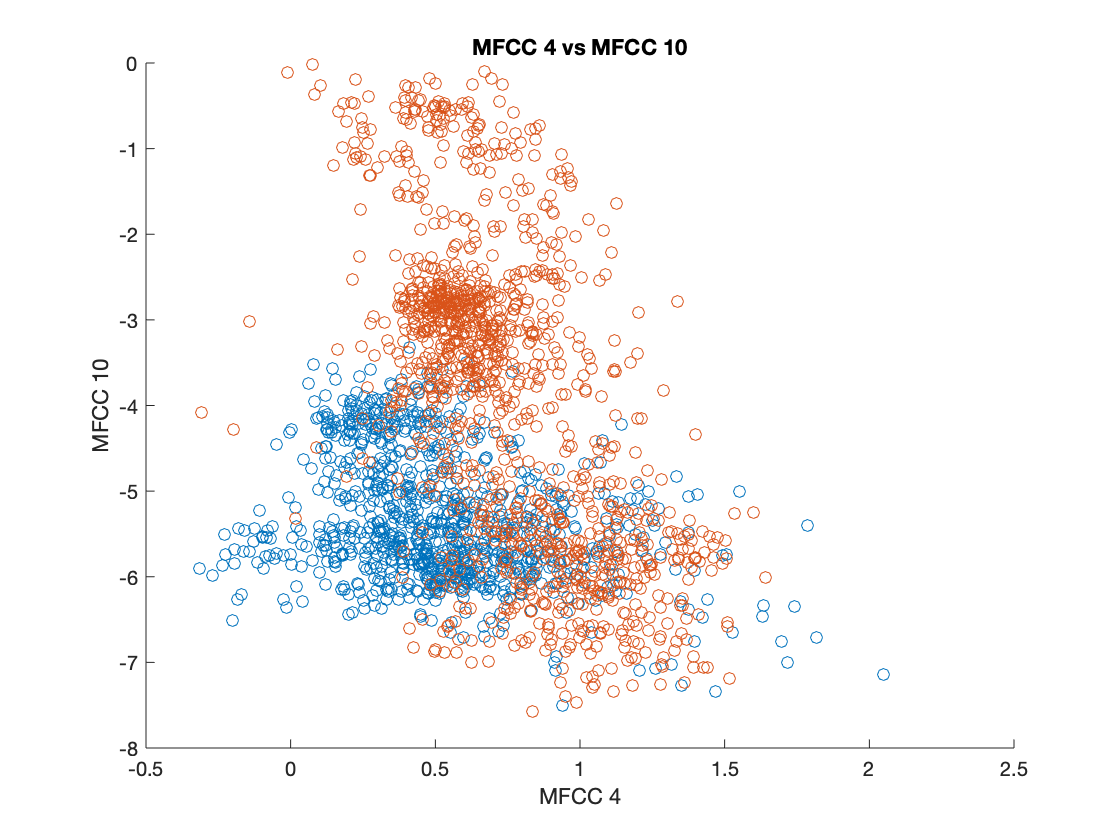

isCovid = [T.label]';
featureCovid = [T(isCovid == 1,:).MFCCParams_10 T(isCovid == 1,:).MFCCParams_4];
featureNonCovid = [T(isCovid == 0,:).MFCCParams_10 T(isCovid == 0,:).MFCCParams_4];

clf
scatter(featureCovid(:,1),featureCovid(:,2)); hold on; scatter(featureNonCovid(:,1),featureNonCovid(:,2))
title("MFCC 4 vs MFCC 10")
xlabel("MFCC 4");
ylabel("MFCC 10");

### EN İYİ FEATURE

Toplam 8 Feature ile eğittiğimiz sınıflandırıcı için hangi feature'ların daha ayırıcı olduğunu sorguladım. Bunun için Forward Feature Selection tekniğini denedim ve sonuçlar şu şekilde oldu.

X_label = T(:,1);
X_train_label = X_label(randoms(1:size(T,1)),1);


%% FORWARD
opts = statset('display','iter');
 
classf = @(train_data, train_labels, test_data, test_labels)...
     sum(...
     predict(...
     fitctree(...
     train_data, ...
     train_labels, ...
     'SplitCriterion', 'gdi', ...
     'MaxNumSplits', 100, ...
     'Surrogate', 'off', ...
     'ClassNames', [0; 1])...
     ,test_data) ~= test_labels);
 
 c = cvpartition(X_train_label{:,:},'k',5);
 
[fs, history] = sequentialfs(classf, X_train{:,:}, X_train_label{:,:}, 'cv', c, 'options', opts,'direction','forward');

Start forward sequential feature selection:
Initial columns included:  none
Columns that can not be included:  none
Step 1, added column 18, criterion value 0.246424
Step 2, added column 24, criterion value 0.183203
Step 3, added column 14, criterion value 0.136594
Step 4, added column 19, criterion value 0.112598
Step 5, added column 17, criterion value 0.0955238
Step 6, added column 3, criterion value 0.0890632
Step 7, added column 21, criterion value 0.0867559
Final columns included:  3 14 17 18 19 21 24 


Sonuçlardan görüldüğü gibi en ayırt edici feature tahmin edildiği gibi Mell Frequency Cepstral'dan 4 ve 10'uncu coefficientlar olmuştur. Sonra da Tonality index gelmektedir. Tonality Index ve MFCC birlikte 92,1% doğruluk oranına ulaşmaktadır.

### Öksürük Sesi Örneğinden Covid Teşhisi

Son olarak 5 saniyelik bir öksürük sesinin covid'li olup olmadığına karar vermek için aşağıdaki algoritma izlenebilir.

- Öksürük Sesi 24 ms'llık windowlara ayrılır. (1024 samples 25% overlap)

- Her bir window için feature hesaplaması yapılır.

- Sonra windowlar bu modelle tahmin edilerek labellanır.

- Burada ufak bir treshold konularak Covid sonucu söylenir. (Örneğin windowların %80'ininden fazlası Covid positif ise öksürük Covid'lidir. )

Bu testleri elimde yeterli öksürük verisi olmasığı için yapamadım.

### Web Sitesi

Daha fazla öksürük sesine ulaşıp modeli geliştimek için bir web sitesi hazırladım.

## Öksürük seslerinizi kaydedin,

## Covid-19 araştırmamıza destek olun.

[https://caglayan.github.io/covid19/](https://caglayan.github.io/covid19/)